## Tutorial 3: Understanding the preprocessing module

In this tutorial, we provide a brief introduction to EXTRACT’s preprocessing module. Here, we discuss loading (and watching) Ca2+ imaging movies from the h5 files, fast spatial high-pass filtering using EXTRACT’s GPU accelerated bandpass filter, and other supporting functions for the preprocessing pipeline. 

setupEXTRACT; % add EXTRACT to the path if it is not already there

### Reading and watching calcium movies

To load the calcium movies with h5read, we first need to :

info = h5info(Example_1p_movie);
info.Datasets.Name

ans = 'mov'

info.Datasets.Dataspace

ans = struct with fields:
       Size: [100 100 5000]
    MaxSize: [100 100 5000]
       Type: 'simple'


This function provides the name of the dataset: '/mov'. The FOV is 100x100, and there are a total of 5000 frames. Now, we show how to use the h5read function native to Matlab to retrieve the first 1000 frames of the movie:

M = h5read(Example_1p_movie,'/mov', ...
    [1,1,1],[100,100,1000]);

More information on this function can be found in [this link](https://www.mathworks.com/help/matlab/ref/h5read.html).

EXTRACT has several helper functions. One particularly useful function allows visualizing the calcium imaging movies. Here is how to use it:

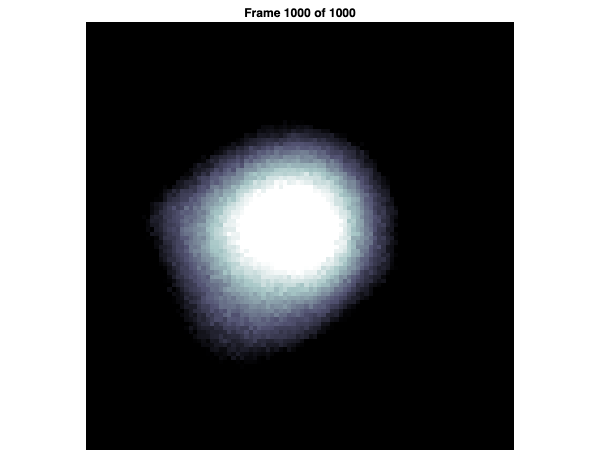

view_movie(M)

### Spatial high-pass filtering in EXTRACT

EXTRACT has an internal spatial band-pass filtering function, which we use to perform highpass filtering during the preprocessing module. Below is an example movie that is filtered to remove the neuropil contamination.

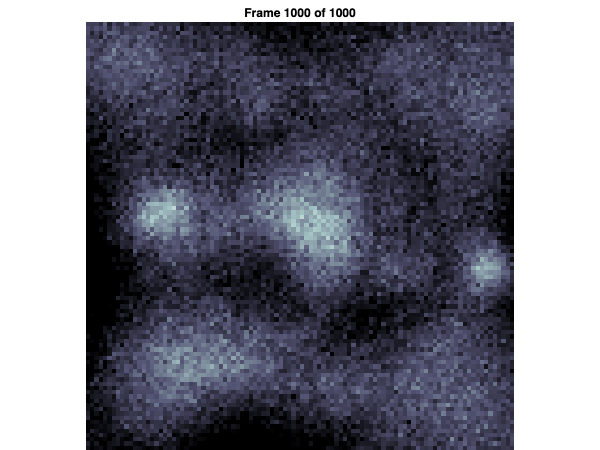

avg_cell_radius = 6;
spatial_highpass_cutoff = 5;
spatial_lowpass_cutoff = inf;
use_gpu = 0;
M_proc = spatial_bandpass(M, avg_cell_radius, ...
  spatial_highpass_cutoff, spatial_lowpass_cutoff, ...
  use_gpu);
view_movie(M_proc)

As shown in the movie on the right, the global background is removed with the selective high-pass spatial filtering and individual cell activities can easily be recovered.

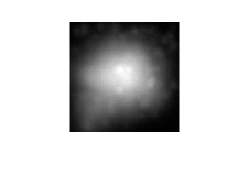

figure
imshow(max(M,[],3),[])
exportgraphics(gcf,'FigA.eps','ContentType','vector')

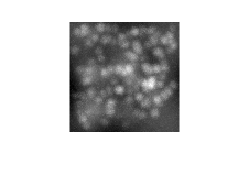

figure
imshow(max(M_proc,[],3),[])
exportgraphics(gcf,'FigB.eps','ContentType','vector')

#### Processing patches individually?

Now, what if we were to process this calcium imaging movie in spatial batches? How should we perform the high-pass filtering? An option is to upload the small batch and perform the filtering on it, which would give:

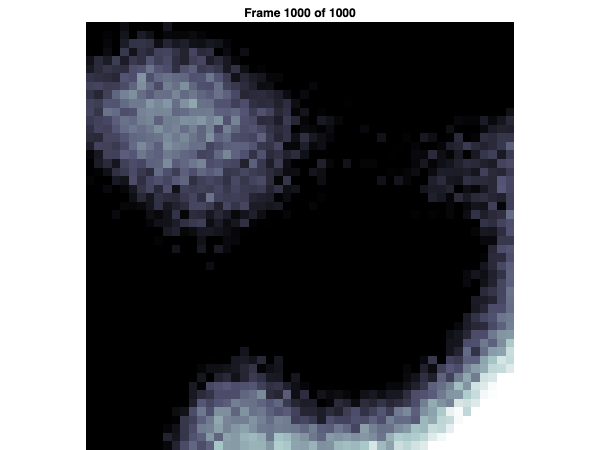

M_small = h5read(Example_1p_movie,'/mov', ...
    [1,1,1],[50,50,1000]);
M_proc_small = spatial_bandpass(M_small, avg_cell_radius, ...
  spatial_highpass_cutoff, spatial_lowpass_cutoff, ...
  use_gpu);
view_movie(M_proc_small)

Here, one can clearly obseve the edge effects that were not present in the original movie. These edge effects are expected, since we are performing a global spatial filtering on a local small spatial patch. 

#### Processing the full FOV?

A better alternative for spatial filtering is to process and save the full movie, but keep only the relevant fraction in RAM memory. In our example, following such a procedure, the small processed spatial patch would look as follows:

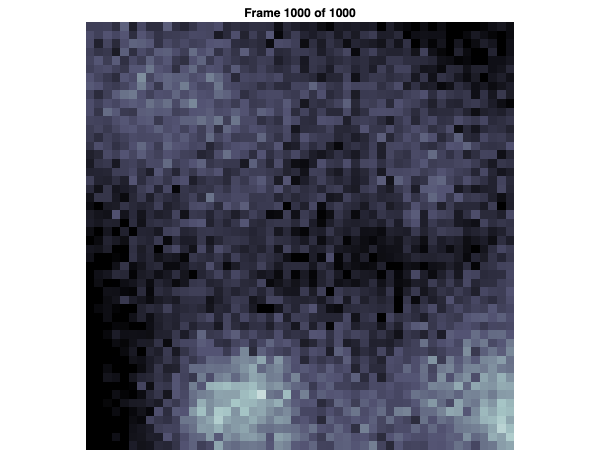

view_movie(M_proc(1:50,1:50,:))

This is a significant improvement compared to before. But, to achieve this, we had to keep the full movie in the memory. Or did we? 

### **Preprocessing and saving movies in batches**

Fortunately, the spatial filtering does not require any temporal information and can be parallelized across individual frames. Therefore, even when the full movie cannot be kept in memory, one can perform the spatial filtering in batches of few hundreds of frames. For EXTRACT, we provided the following helper function to facilitate this process:

config = get_defaults([]);
config.partition_size_time = 500;
preprocess_save([Example_1p_movie ':/mov'],config)

25-Jul-2024 16:44:02: No GPU detected, using CPU instead
25-Jul-2024 16:44:03: Calculating F_per_pixel ... 
	 	 	 25-Jul-2024 16:44:03: Running 1 out of 5 parts 
	 	 	 25-Jul-2024 16:44:03: Running 2 out of 5 parts 
	 	 	 25-Jul-2024 16:44:03: Running 3 out of 5 parts 
	 	 	 25-Jul-2024 16:44:03: Running 4 out of 5 parts 
	 	 	 25-Jul-2024 16:44:03: Running 5 out of 5 parts 
25-Jul-2024 16:44:03: Running Highpass filtering ... 
	 	 	 25-Jul-2024 16:44:03: Running 1 out of 10 parts 
	 	 	 25-Jul-2024 16:44:03: Running 2 out of 10 parts 
	 	 	 25-Jul-2024 16:44:03: Running 3 out of 10 parts 
	 	 	 25-Jul-2024 16:44:04: Running 4 out of 10 parts 
	 	 	 25-Jul-2024 16:44:04: Running 5 out of 10 parts 
	 	 	 25-Jul-2024 16:44:04: Running 6 out of 10 parts 
	 	 	 25-Jul-2024 16:44:04: Running 7 out of 10 parts 
	 	 	 25-Jul-2024 16:44:05: Running 8 out of 10 parts 
	 	 	 25-Jul-2024 16:44:05: Running 9 out of 10 parts 
	 	 	 25-Jul-2024 16:44:05: Running 10 out of 10 parts 
25-Jul-2024 16:44

The full preprocessed movie is saved as Example_1p_movie_final.h5. 

Here is how to use this movie to perform cell extraction:

Example_1p_movie_final = char(fullfile(whichEXTRACT(),...
    "Learning-materials","Sample data","Example_1p_movie_final.h5"));

M = h5read(Example_1p_movie_final,'/mov');
config = get_defaults([]);
config.preprocess = 0;
config.use_gpu = 0;
config.cellfind_max_steps = 120;
config.thresholds.eccent_thresh = 3;
config.thresholds.size_upper_limit = 3;
config.cellfind_adaptive_kappa = 1;
config.adaptive_kappa = 2;
config.trace_output_option = 'no_constraint';
config.F_per_pixel = h5read(Example_1p_movie_final,'/F_per_pixel');
output = extractor(M,config);

25-Jul-2024 16:44:05: Signal extraction will run on 1 partitions serially... 
25-Jul-2024 16:44:05: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Using the provided pre-processed movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 	 noise std: 0.0078 
	 	 	 	 minimum magnitude: 0.0108 
			 Step #100, found 100 cells... 
	 	 	 119 cells found after a total of 120 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 115 (4 removed) 
	 	 	 End of iter # 2: # cells: 107 (8 removed) 
	 	 	 End of iter # 3: # cells: 102 (5 removed) 
	 	 	 End of iter # 4: # cells: 101 (1 removed) 
	 	 	 End of iter # 5: # cells: 101 (0 removed) 
	 	 	 End of iter # 6: # cells: 101 (0 removed) 
	 	 	 Providing traces with robust regression and no non-negativity constraint... 
	 	 	 Count: 101 cells.
25-Jul-2024 16:48:01: Total of 101 cells are found.
25-Jul-2024 16:48:01: Removing 

As before, since this is a simulated calcium imaging movie, we can compute the quality metrics for the cell extraction.

Example_1p_movie_mat = char(fullfile(whichEXTRACT(),...
    "Learning-materials","Sample data","Example_1p_movie.mat"));
a = load(Example_1p_movie_mat);

[recall,precision,ampcor,auc] = get_simulation_results(a,output);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.



fprintf("Prc %.3f. Rcl %.3f. Ampcor %.3f. AUC %.4f. \n", ...
    precision,recall,ampcor,auc);

Prc 0.990. Rcl 1.000. Ampcor 0.930. AUC 0.9941. 


Finally, we can visualize a few cells' activity traces to show that the spatial filtering does not affect the cell extraction results, which is true by definition since filtering occurs in larger spatial distances compared to single cell radius.

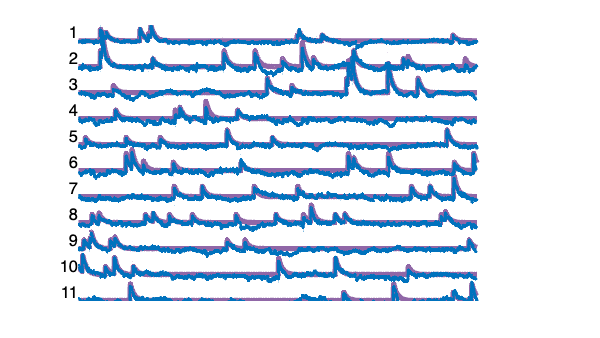

S_ground = a.mov_2p.S;
T_ground = a.mov_2p.T;
[h,w,k]=size(full(output.spatial_weights));
S_ex=reshape(full(output.spatial_weights),h*w,k);
idx_match = match_sets(S_ex, S_ground,0.8); 
T_ex = output.temporal_weights';
T_ex = T_ex ./ max(T_ex,[],2);
T_ground = T_ground ./ max(T_ground,[],2);
color_extract = [0 0.4470 0.7410];
color_gt      = [144 103 167]./255;
plot_stacked_traces_double(T_ground(idx_match(2,1:11),1:1030), ...
 T_ex(idx_match(1,1:11),1:1030),1,{color_gt,color_extract},[],[],{5,3});
exportgraphics(gcf,'FigC.eps','ContentType','vector')